# Task-1

x = [1, 6, 1, 4];
h = [4, 5, 0, 6, 0, 9];

y = conv(x, h);
yc = cconv(x, h);
yc2 = cconv(x, h, max(length(x), length(h)));
figure;
subplot(3, 1, 1);   
stem(y);
grid on;
xlabel('n', 'interpreter', 'latex');
title('Linear Convolution', 'interpreter', 'latex');

In **circular convolution, **here length of the final output is $N_1 + N_2 - 1$ and it is same as **Linear Convolution**, so there won't be any aliasing

subplot(3, 1, 2);
stem(yc);
xlabel('n', 'interpreter', 'latex');
title('Circular Convolution', 'interpreter', 'latex');
grid on;


Now, if we take N-point Cicular convolution where $N = \max(size(x), size(h))$ then, there will be aliasing which we can observe by shifting and adding linear convolution by $N$,

In summary, 


$$w[n] = \begin{cases}
\sum_{r=-\infty}^{\infty} y[n-rN], &\quad 0 \leq n \leq N-1 \\
0, &\quad \text{otherwise}
\end{cases}$$


where $y[n]$ is linear convolution

disp(y);

     4    29    34    27    56    15    78     9    36



disp([zeros(1, 6) y]);

     0     0     0     0     0     0     4    29    34    27    56    15    78     9    36



disp([zeros(1, 6) fix(yc2)]);

     0     0     0     0     0     0    82    38    70    27    56    15



Now as we can observe, there is aliasing in last three elements, which can be verified by above expression

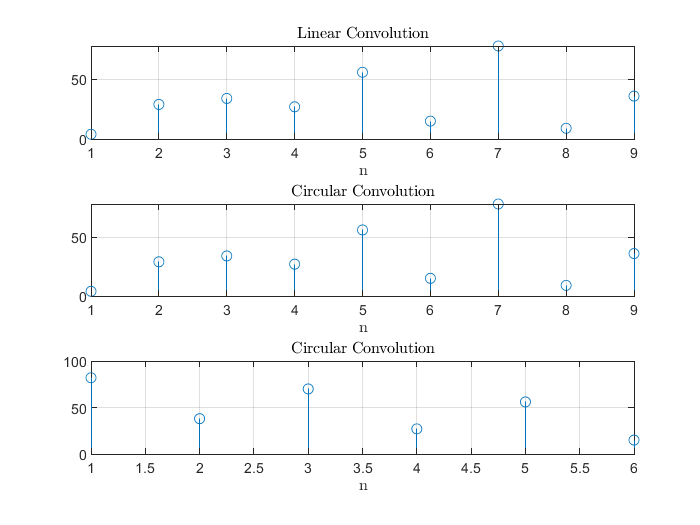

subplot(3, 1, 3);
stem(yc2);
xlabel('n', 'interpreter', 'latex');
title('Circular Convolution', 'interpreter', 'latex');
grid on;